clear, close all
clc

# Analysis of the Frequency Sweeps on the Prototype

This LiveScript aims to do analyse the recordings obtained feeding the prototype with logarithmics sinesweeps from 1 Hz to 10 kHz following the guidelines of Farina's [1] publication. 

[1] A. Farina, “Simultaneous measurement of impulse response and distortion with a swept-sine technique,” p. 24.  

## Read the audio files

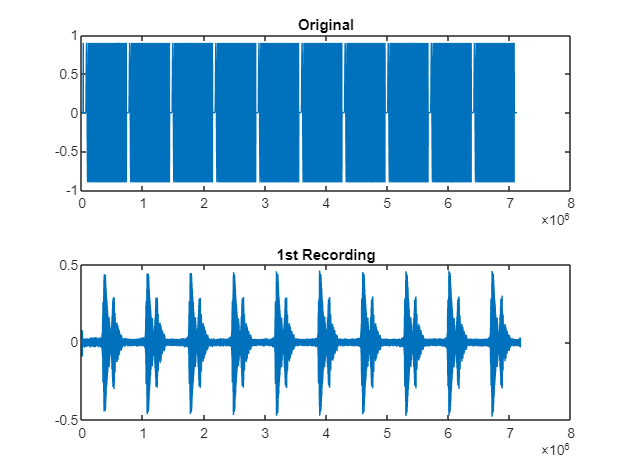

% The audiofiles are composed by 2 channels. The used one is the second, thus
% we can ignore the other one.

% Read the folder content.
folder = dir("Recordings\");

% Create variables to name struct's fields
field1 = 'name';
field2 = 'audio';
audioFiles = struct([]);

% For every file of the folder that it's not a folder iteself
for idx = 1 : size(folder, 1)

    % Load a struct containing name and audiofile
    if folder(idx).isdir ~= 1
        tmp = struct(field1, folder(idx).name, field2, ...
            audioread(append(folder(idx).folder, '\', ...
            folder(idx).name)));

        % Select only the 2nd audio channel (container of the IR) and save
        audioFiles = cat(1, audioFiles, struct(field1, tmp.name, field2, ...
            tmp.audio(:, 2)));

        lastFileIdx = idx;
    end
end

% Load the original log sine sweep
[sineSweep, fsSineSweep] = audioread("Sweep_1_10000.wav");

% Load the sampling frequency of the recorded files

[~, fsRec] = audioread(append(folder(lastFileIdx).folder, '\', ...
    folder(lastFileIdx).name));

%% Plot original
figure
tiledlayout(2, 1)
nexttile
plot(sineSweep(:, 1))
title("Original")

nexttile
plot(audioFiles(1).audio)
title("1st Recording")

## Align the signals

In the original audio file of the sine sweep an impulse with Gaussian window shape has been used to facilitate the allignment between the original file and the recordings. 

% Find the peak of the Gaussian win shape in the first 44100 samples
[~, maxOrig] = max(abs(sineSweep(1 : fsRec)));

% Slide the original signal to begin with the peak of the Gaussian bell
slidedOrig = sineSweep(maxOrig : end, 1);

## Plot the frequencies responses 

Select between single position of measurement or mean of all positions.

% Select between single position analysis and all position analysis
allPositions = true;
plotAllResponsesComparison = false;

decibel = true;
grid = true;
xlog = false;

### Plot time domain, FFT and Spectrogram of each position

% === Mean of the ten repetitions ===
if allPositions == false && plotAllResponsesComparison == true

    for selectedFile = 1 : size(audioFiles, 1)

        % Find the max of 1 sec in the recorded file
        % corr1Sec = xcorr(sineSweep(1 : fsRec), audioFiles(selectedFile).audio(1 : fsRec));
        % [~, sampleHook] = max(corr1Sec);
        [~, sampleHook] = max(abs(audioFiles(selectedFile).audio(1 : fsRec)));


        % Slide the record to align the origioknal file with the original sweep
        slided = audioFiles(selectedFile).audio(sampleHook : end, :);

        % Plot the two signals aligned
        %         figure
        %         plot(normalize(slidedOrig))
        %         hold on
        %         plot(normalize(slided))
        %         hold off
        %         title('Original and recording aligned')

        % Considering that the input sweep is long 15 seconds, cut the recording in
        % 10 different slices and do the mean of the 10 recordings.

        % The sineSweep is composed by: 0.5 seconds of silence, 100 samples of Gaussian win,
        % [1 sec of silence, 15 sec of sweep] * 10

        nSamplesSweep = 15 * fsSineSweep;
        responses = zeros(nSamplesSweep, 1);

        % Skip half of the Gaussian win (peak) and one second of silence
        slided = slided(fsRec/2 + 50 + fsRec : end);

        % Sum all the repetitions (10 times)
        for i = 0 : 9
            tmp = slided((nSamplesSweep + fsRec) * i + 1 : (nSamplesSweep + fsRec)* i + nSamplesSweep);
            responses = responses + tmp;
        end

        % Obtain the average of the repetitions
        responses = responses / 10;

        graphTitle = erase(audioFiles(selectedFile).name, '.wav');
        graphTitle = erase(graphTitle, 'Rec');
        graphTitle = erase(graphTitle, '_');


        subplot(3, 7, selectedFile)
        plot(responses);
        ylim([-0.3 0.3])
        title(graphTitle)
        subplot(3, 7, 7 + selectedFile)
        PlotFFT(responses, fsRec, 1000, 'FFT', decibel, grid, xlog);
        subplot(3, 7, 14 + selectedFile)
        PlotSpectrogram(responses, fsRec, 512, 64, 512, 1000);

    end
end

### Mean of all repetitions for single position

% === Mean of the ten repetitions ===
if allPositions == false

    selectedFile = 1;

    % Find the max of 1 sec in the recorded file
    % corr1Sec = xcorr(sineSweep(1 : fsRec), audioFiles(selectedFile).audio(1 : fsRec));
    % [~, sampleHook] = max(corr1Sec);
    [~, sampleHook] = max(abs(audioFiles(selectedFile).audio(1 : fsRec)));


    % Slide the record to align the origioknal file with the original sweep
    slided = audioFiles(selectedFile).audio(sampleHook : end, :);

    % Considering that the input sweep is long 15 seconds, cut the recording in
    % 10 different slices and do the mean of the 10 recordings.

    % The sineSweep is composed by: 0.5 seconds of silence, 100 samples of Gaussian win,
    % [1 sec of silence, 15 sec of sweep] * 10

    nSamplesSweep = 15 * fsSineSweep;
    responses = zeros(nSamplesSweep, 1);

    % Skip half of the Gaussian win (peak) and one second of silence
    slided = slided(fsRec/2 + 50 + fsRec : end);

    % Sum all the repetitions (10 times)
    for i = 0 : 9
        tmp = slided((nSamplesSweep + fsRec) * i + 1 : (nSamplesSweep + fsRec)* i + nSamplesSweep);
        responses = responses + tmp;
    end

    % Obtain the average of the repetitions
    responses = responses / 10;


    graphTitle = erase(audioFiles(selectedFile).name, '.wav');
    graphTitle = erase(graphTitle, 'Rec');
    graphTitle = erase(graphTitle, '_');


    figure
    plot(normalize(slidedOrig))
    hold on
    plot(normalize(slided))
    hold off
    title('Original and recording aligned')


    figure
    PlotFFT(responses, fsRec, 1000, graphTitle, decibel, grid, xlog);
    figure
    PlotSpectrogram(responses, fsRec, 512, 64, 512, 1000, graphTitle);
end

### Single slice

singleSlice = false;

% === Single slice analysis ===
if allPositions == false && singleSlice == true

    selectedSlice = 6;

    slice = slided((nSamplesSweep + fsRec) * selectedSlice + 1 : (nSamplesSweep + fsRec) * selectedSlice + nSamplesSweep);
    originalSingleSweep = slidedOrig((50 + fsSineSweep) : ...
        (fsSineSweep * 15 + 50 + fsSineSweep) - 1);

    figure
    plot(originalSingleSweep)
    hold on
    plot(normalize(slice, 1, "range") - 0.5)
    hold off
    title(sprintf('Signals aligned in slice %i', selectedSlice))

    figure
    PlotFFT(responses, fsRec, 1000, 'Single Slice', decibel, grid, xlog);

    figure
    PlotSpectrogram(slice, fsRec, 512, 64, 512, 1000);

end

### Analysis of mean of all positions and repetitions

% === Analysis of mean of all positions and mean of all repetitions ===
if allPositions == true

    allRecordings = zeros(size(audioFiles(1).audio));

    % Load all the audioFiles and do a mean
    for i = size(audioFiles, 1)
        allRecordings = allRecordings + audioFiles(i).audio;
    end

    % Normalize
    allRecordings = allRecordings / size(audioFiles, 1);

    % Find the max of 1 sec in the recorded file
    % corr1Sec = xcorr(sineSweep(1 : fsRec), audioFiles(selectedFile).audio(1 : fsRec));
    % [~, sampleHook] = max(corr1Sec);
    [~, sampleHook] = max(abs(allRecordings(1 : fsRec)));


    % Slide the record to align the origioknal file with the original sweep
    slided = allRecordings(sampleHook : end, :);

    % Considering that the input sweep is long 15 seconds, cut the recording in
    % 10 different slices and do the mean of the 10 recordings.

    % The sineSweep is composed by: 0.5 seconds of silence, 100 samples of Gaussian win,
    % [1 sec of silence, 15 sec of sweep] * 10

    nSamplesSweep = 15 * fsSineSweep;
    responses = zeros(nSamplesSweep, 1);

    % Skip half of the Gaussian win (peak) and one second of silence
    slided = slided(fsRec/2 + 50 + fsRec : end);

    % Sum all the repetitions (10 times)
    for i = 0 : 9
        tmp = slided((nSamplesSweep + fsRec) * i + 1 : (nSamplesSweep + fsRec)* i + nSamplesSweep);
        responses = responses + tmp;
    end

    % Obtain the average of the repetitions
    responses = responses / 10;
end


# Filter design

## Design n-Band Parametric Equalizer

Specify the filter order, peak gain in dB, normalized center frequencies, and normalized bandwidth of the bands of your parametric equalizer.

simple = false;
freqPalmCompensation = false;

if simple == true
    centerFreq =    [35, 50,  75,  105, 400, 730, 900];
    bandwidth =     [60, 1,   30,  90,  70, 100, 500];
    gain =          [6, -40, -6, -10,   8,   6,   12];
    nFilters = length(centerFreq);
    orders = ones(1, nFilters) * 2;

    if freqPalmCompensation == true
        centerFreq = cat(2, centerFreq, 250);
        bandwidth = cat(2, bandwidth, 400);
        gain = cat(2, gain, -20);
        nFilters = length(centerFreq);
        orders = ones(1, nFilters) * 2;
    end
else
    centerFreq = [15,  28, 35, 44,   50,  50,  56,  75,  120, 205, 260, 370, 400, 490, 545, 555, 555, 620, 735, 795, 800, 825, 850, 855, 875];
    bandwidth =  [30,  10, 30, 10,   1,   20,  8,   40,  30,  30,  50,  80,  80,  30,  200, 30,  5,   20,  5,   50,  10,  350, 20,  5,   30];
    gain =       [+5, -10,  10, -20, -40,  15, -8,  -10, -10,  5,   5,   -5,  10,  10, -5,   10,  5,   8,  -5,  -5,  -5,   15,  5,  -5,   -5];
    nFilters = length(centerFreq);
    orders = ones(1, nFilters) * 4;

    if freqPalmCompensation == true
        centerFreq = cat(2, centerFreq, 250);
        bandwidth = cat(2, bandwidth, 400);
        gain = cat(2, gain, -20);
        nFilters = length(centerFreq);
        orders = ones(1, nFilters) * 2;
    end
end

% Normalize
centerFreq = centerFreq / (fsRec / 2);
bandwidth = bandwidth / (fsRec/2);

Generate the filter coefficients using the specified parameters.

[B,A] = designParamEQ(orders,gain,centerFreq,bandwidth);

Visualize your filter design.

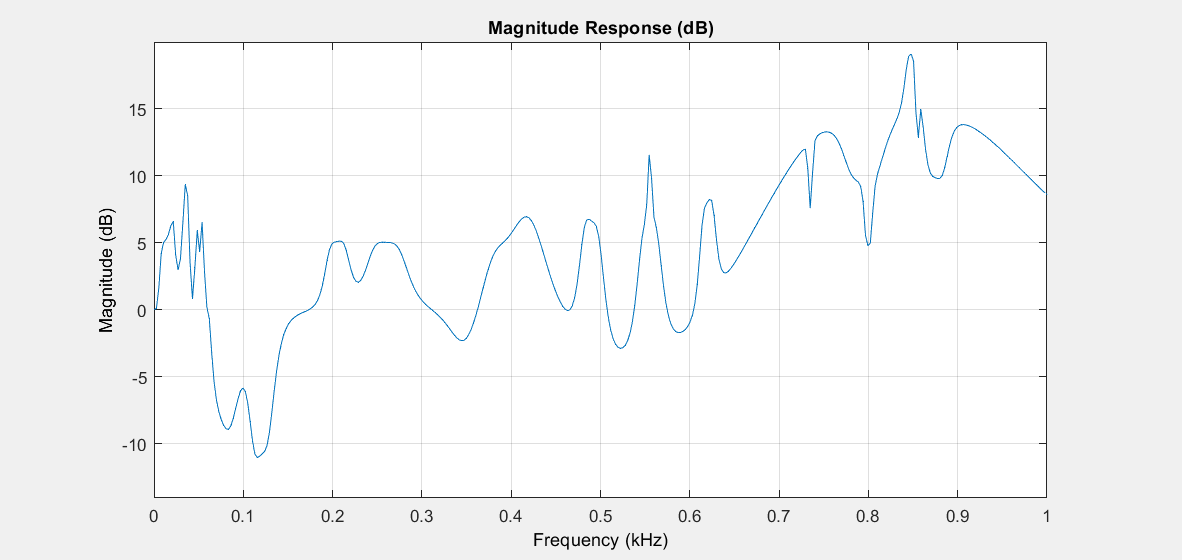

myFilter = dsp.BiquadFilter( ...
    "SOSMatrixSource","Input port", ...
    "ScaleValuesInputPort",false);
equalizedSignal = myFilter(responses,B,A);

% For visualization
[Bvisualize,Avisualize] = designParamEQ(orders,gain,centerFreq,bandwidth,"Orientation","row");
fvtool([Bvisualize,Avisualize],'fs', fsRec);
xlim([0 1]);

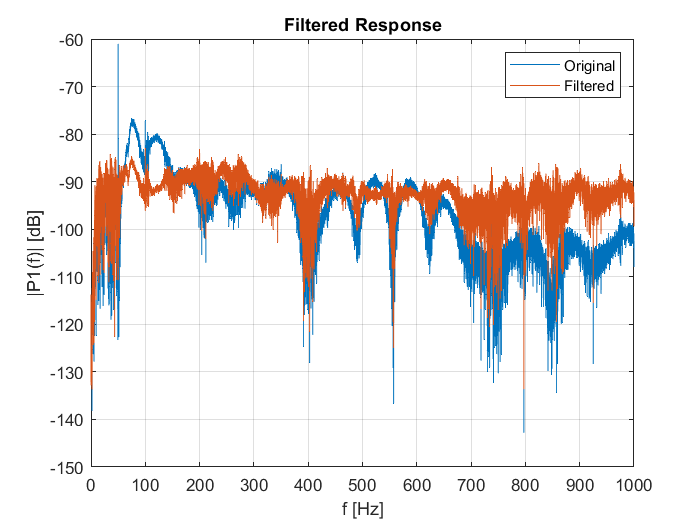


figure
PlotFFT(responses, fsRec, 1000, 'Original Response', decibel, grid, xlog, false);
hold on
PlotFFT(equalizedSignal, fsRec, 1000, 'Filtered Response', decibel, grid, xlog, false);
hold off
legend('Original', 'Filtered');

# Apply the filter

Filter an audio example to test with the haptic device.

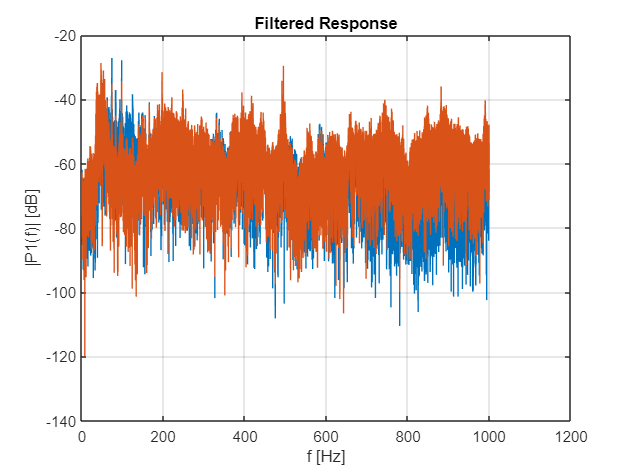

[song, fsSong] = audioread('..\Audio_Sources\Sound&Color_Cut.mp3');
% Apply the filter only on the second repetition of the song.
firstPartSong = song(1 : fsSong * 45 - 1, :);
secondPartSong = song(fsSong * 45 : end, :);
secondPartSong(:, 1) = myFilter(secondPartSong(:, 1), B, A);
secondPartSong(:, 2) = myFilter(secondPartSong(:, 2), B, A);

PlotFFT(firstPartSong, fsSong, 1000, 'Original Response', decibel, grid, xlog, false);
hold on
PlotFFT(secondPartSong, fsSong, 1000, 'Filtered Response', decibel, grid, xlog, false);
hold off

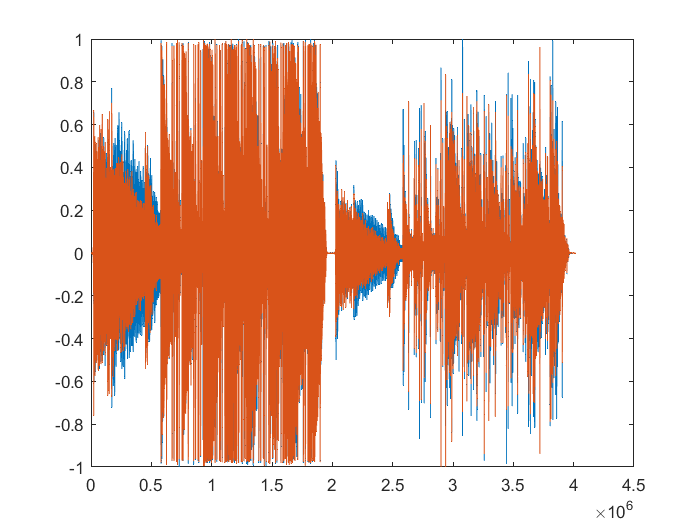


%Normalize
secondPartSong = secondPartSong ./ (max(abs(secondPartSong)));

filteredSong = cat(1, firstPartSong, secondPartSong);

plot(filteredSong);


audiowrite('../Audio_Sources/Sound&Color_Cut_Filtered.flac', filteredSong, fsSong);

## Save results to file

%% For Juce
% Write the A coefficients in a txt file
fileIDB = fopen('B.txt','w');
fprintf(fileIDB,'%.10f %.10f %.10f\n', B);
fclose(fileIDB);

% Write the A coefficients in a txt file
fileIDA = fopen('A.txt','w');
fprintf(fileIDA,'%.10f %.10f\n', A);
fclose(fileIDA);

%% For PureData
allCoeffs = cat(1, -A, B);
% Write the A coefficients in a txt file
fileIDP = fopen('FilterCoefficients.txt','w');
fprintf(fileIDP,'%.10f %.10f %.10f %.10f %.10f;\n', allCoeffs);
fclose(fileIDP);